# MECH 320 Finite Element Method Project

## Introduction

Modelling this 

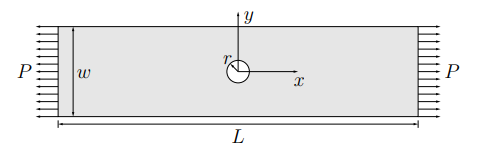

and this

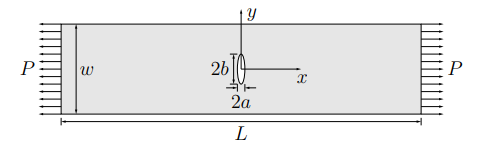

## Results

First we build the model to show the plate geometry and generated mesh

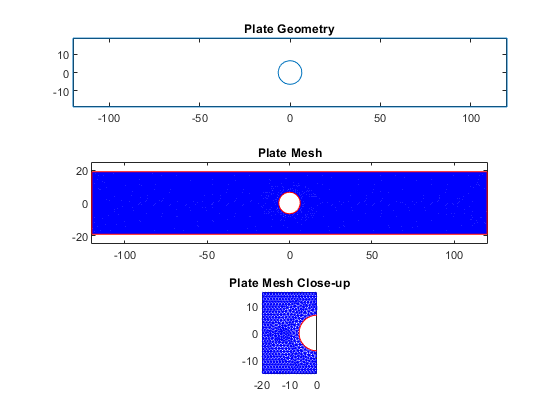

clc
clear all
close all

%% 1: Model parameters
half_crack_height = 6.5;       % Half crack height (mm)
half_crack_width = 1;        % Half crack width (mm)
half_width = 38/2;              % Plate half width (mm)
half_length = 240/2;             % Plate half length (mm)
youngs_modulus = 200*10^3;          % Youngs Modulus of material (MPa)
poissons_ratio = 0.3;          % Poissons ration of material

surf_traction = 10;           % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% Vector representing rectangular plate geometry
plate = [3 4 -half_length half_length half_length -half_length -half_width -half_width half_width half_width]';

% Vector representing circular or elliptical hole geometry
hole = [1 0 0 half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model,geom);

% Specify material properties
structuralProperties(model,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model,'Edge',3,'XDisplacement',0);
structuralBC(model,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model,'Hmax',mesh_size);

% Solve system of equations
sol = solve(model);

%% 4: Plotting

figure
tiledlayout(3,1)
% Geometry
nexttile          % Create figure
pdegplot(model); % Plot model geometry
axis equal       % Set equal scales for x and y axes
title('Plate Geometry');    % Plot title

% Mesh
nexttile
pdemesh(model); % Plot model mesh
axis equal    % Set equal scales for x and y axes
title('Plate Mesh');   % Plot title

%Mesh Close up
nexttile
pdemesh(model); % Plot model mesh
xlim([-20 0]);
ylim([-15 15]);
title('Plate Mesh Close-up');   % Plot title

Then we find the stress and displacement distribution created by the applied load P

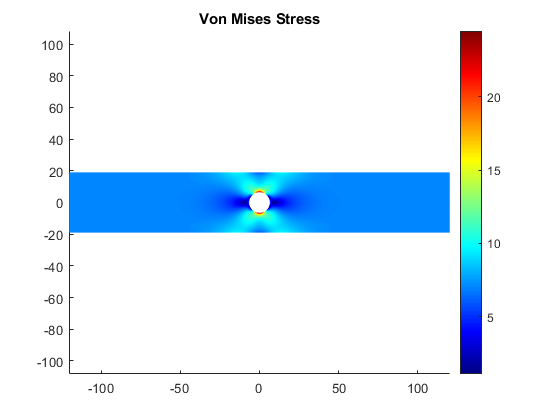

% Von Mises stress contours
svon = 0.5.*sqrt((sol.Stress.sxx-sol.Stress.syy).^2+(0-sol.Stress.sxx).^2+6*(sol.Stress.sxy).^2);   % Calculate von Mises stress

figure                                         % Create figure
pdeplot(model,'XYData',svon,'ColorMap','jet'); % Plot xy data (in this case the von Mises stress)
axis equal                                     % Set equal scales for x and y axes
title('Von Mises Stress');                     % Plot title

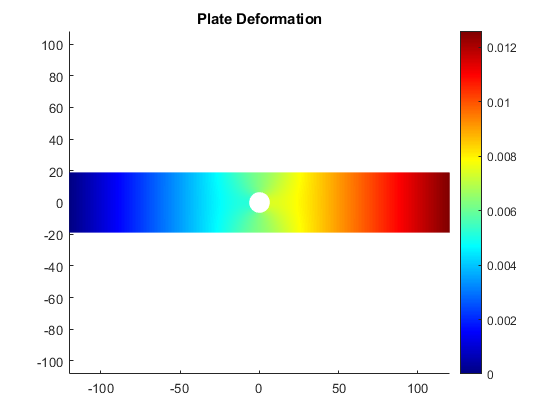


% Deformed shape
figure                                         % Create figure
pdeplot(model,"XYData",sol.Displacement.x,"Deformation",sol.Displacement,"DeformationScaleFactor",plot_scale_factor,"ColorMap","jet"); % Plot xy data (in this case displacement and deformation superimposed)
axis equal                                     % Set equal scales for x and y axes
title('Plate Deformation');                    % Plot title

Then calculate the stre

%% 5: Calculate stress concentrantion factor
p = [-100,0];                         % Coordinates of point far away from the hole
snom = interpolateStress(sol,p').xx; % Nominal stress x obtained at point far away from hole
smax = max(sol.Stress.sxx);        % Maximum normal stress x in the plate
%k = 1+2*(half_crack_height/half_crack_width);     % Stress concentration factor for ellipse
k = 1+2*(1);
fprintf("k = %d\n",k);               % Print k to the console

k = 3


fprintf("snom = %d\n",snom);               % Print nominal steess to the console

snom = 1.000015e+01


fprintf("smax = %d\n",smax);               % Print max stress to the console

smax = 3.480654e+01


## Discussion of Results

## Concluding Remarks

## References